clear
fs = 800e3

fs = 800000

cutoff = 40e3

cutoff = 40000

trans_width = 20e3

trans_width = 20000


pass_ripple = 1;
stop_att = 80;
dev = [(10^(pass_ripple/20)-1)/(10^(pass_ripple/20)+1) 10^(-stop_att/20)]; 

[n,fo,ao,w] = firpmord([cutoff cutoff+trans_width],[1 0],dev,fs);
b = firpm(n,fo,ao,w);

x = 0:199;
y = (x>60)*0.874969482421875;
yf = filter(b, 1, y);
% QUANTIZATION OF TAPS
n_bits = 16;
taps = round(2^(n_bits-1)*b);

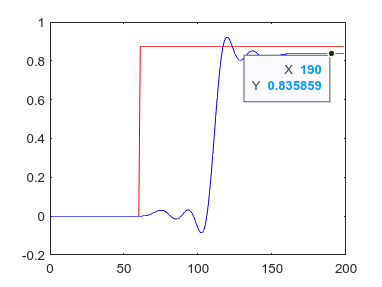

plot(x, y,"-r", x, yf,"-b")

fvtool(b,1)